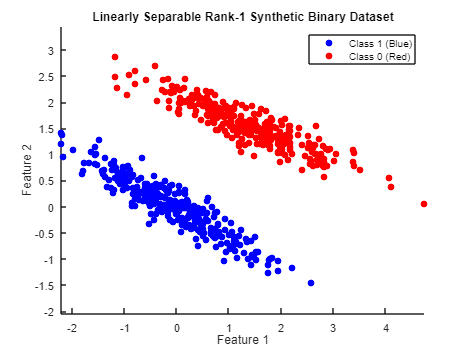

% Parameters
num_points = 600; % Total number of points
class1_angle = -pi/6; % Principal direction for class 1 (45 degrees) pi\4
class2_angle = -pi/8; % Principal direction for class 0 (-30 degrees) -pi\6
noise_level = 0.18; % Small noise to spread points around the principal line 0.1
class_distance =1.5; % Distance between the classes to ensure separability 2

% Generate class 1 points
class1_t = randn(num_points/2, 1); % Parameter along the principal component
class1_x = class1_t * cos(class1_angle) + randn(num_points/2, 1) * noise_level; % Feature 1
class1_y = class1_t * sin(class1_angle) + randn(num_points/2, 1) * noise_level; % Feature 2
class1_labels = ones(num_points/2, 1); % Label = 1

% Generate class 0 points
class2_t = randn(num_points/2, 1); % Parameter along the principal component
class2_x = class2_t * cos(class2_angle) + randn(num_points/2, 1) * noise_level + class_distance; % Feature 1
class2_y = class2_t * sin(class2_angle) + randn(num_points/2, 1) * noise_level + class_distance; % Feature 2
class2_labels = zeros(num_points/2, 1); % Label = 0

% Combine the dataset
X = [class1_x, class1_y; class2_x, class2_y]; % Features
Y = [class1_labels; class2_labels]; % Labels

% Scatter plot of the dataset
figure;
scatter(class1_x, class1_y, 'b', 'filled'); hold on;
scatter(class2_x, class2_y, 'r', 'filled');
title('Linearly Separable Rank-1 Synthetic Binary Dataset');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class 1 (Blue)', 'Class 0 (Red)');
axis equal;


% Save to CSV if needed
dataset = [X, Y]

dataset =    -0.3313    0.3933    1.0000
   -1.0199    0.4976    1.0000
   -0.7688    0.2833    1.0000
   -1.0201    0.6126    1.0000
    0.0076    0.0605    1.0000
    0.4201   -0.1094    1.0000
    0.2027    0.1262    1.0000
    0.5927    0.1098    1.0000
    0.6672   -0.4021    1.0000
   -1.1658    0.5518    1.0000


csvwrite('toy_dataset12.csv', dataset);

disp('Linearly separable dataset created and saved as linearly_separable_rank1_dataset.csv');

Linearly separable dataset created and saved as linearly_separable_rank1_dataset.csv
